# 5.1 数字滤波器的基本概念：IIR 与 FIR、幅频与相频、技术指标（容限图）、信号流图

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB（不需要 Signal Processing Toolbox）。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：IIR 与 FIR 的单位脉冲响应——无限长 vs 有限长（教材例 5.1 与例 5.5 的两个系统）

bI = [1 -3 11 27 18]; aI = [16 12 2 -4 -2];     % 例 5.1：H(z)=(1-3z^-1+11z^-2+27z^-3+18z^-4)/(16+12z^-1+2z^-2-4z^-3-2z^-4)
Nh = 30; delta = [1 zeros(1, Nh-1)];
hI = filter(bI, aI, delta);                       % IIR：分母有反馈，h(n) 无限长
hF = 0.9.^(0:10);                                 % 例 5.5：h(n)=0.9^n，0≤n≤10，FIR
hF30 = [hF zeros(1, Nh-11)];
polesI = roots(aI); maxPole = max(abs(polesI));   % 极点都在单位圆内 → 稳定，h(n) 衰减

## 演示2：频率响应 H(e^jω)=|H|e^{jθ(ω)}：幅频响应与相频响应（教材 5.1.1）

w = linspace(0, pi, 1024);
HI = dtft_resp(bI, aI, w); HF = dtft_resp(hF, 1, w);

## 演示3：技术指标——通带容限 δ1、阻带容限 δ2、边界频率 ωp、ωs 与 dB 换算（教材图 5.1.2、式 (5.1.3)—(5.1.6)）

拿一个现成的低通 FIR（窗函数法，第 7 章会讲怎么来的），量它的指标

Nw = 41; nn = 0:Nw-1; wc = 0.4*pi; alpha = (Nw-1)/2;
hLP = (wc/pi)*mysinc(wc*(nn - alpha)/pi) .* (0.54 - 0.46*cos(2*pi*nn/(Nw-1)));
HL = dtft_resp(hLP, 1, w); magL = abs(HL);
wp = 0.32*pi; ws = 0.48*pi;
d1 = max(abs(magL(w <= wp) - 1));                 % 通带内 |H| 偏离 1 的最大值
d2 = max(magL(w >= ws));                          % 阻带内 |H| 的最大值
ap = -20*log10(1 - d1);                           % 式 (5.1.5)：通带最大衰减（|H(e^j0)| 归一为 1）
as = -20*log10(d2);                               % 式 (5.1.6)：阻带最小衰减
i3 = find(magL <= 1/sqrt(2), 1); w3 = w(i3);      % 3 dB 截止频率：|H|=1/√2

## 演示4：结构表示——习题 5 的一阶系统 y(n)=0.5y(n−1)+x(n)+x(n−1)：信号流图与正弦稳态响应

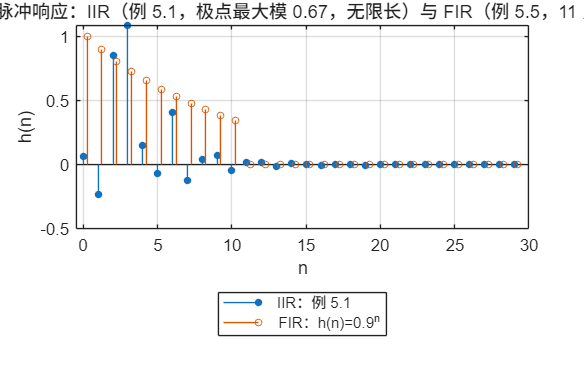

b5 = [1 1]; a5 = [1 -0.5];
fs = 1000; f0 = 100; t = (0:199)/fs; x5 = 10*sin(2*pi*f0*t);   % fs=1 kHz，100 Hz 正弦，幅度 10
y5 = filter(b5, a5, x5);
H5 = dtft_resp(b5, a5, 2*pi*f0/fs);
ys = y5(101:end); ts = t(101:end);                                % 稳态段
cs = [cos(2*pi*f0*ts); sin(2*pi*f0*ts)].' \ ys.';                 % 最小二乘拟合 A·cos + B·sin（峰值不一定正好被采到）
gainTheory = abs(H5); gainMeas = norm(cs)/10;                    % 稳态幅度 / 输入幅度

if ~LIVE, f1 = figure('Name','01 滤波器概念','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); stem(0:Nh-1, hI, 'filled', 'MarkerSize', 4); hold on; stem((0:Nh-1)+0.25, hF30, 'MarkerSize', 4);
grid on; xlim([-0.5 Nh]);
title(sprintf('① 单位脉冲响应：IIR（例 5.1，极点最大模 %.2f，无限长）与 FIR（例 5.5，11 点后为 0）', maxPole));
xlabel('n'); ylabel('h(n)'); legend('IIR：例 5.1', 'FIR：h(n)=0.9^n');

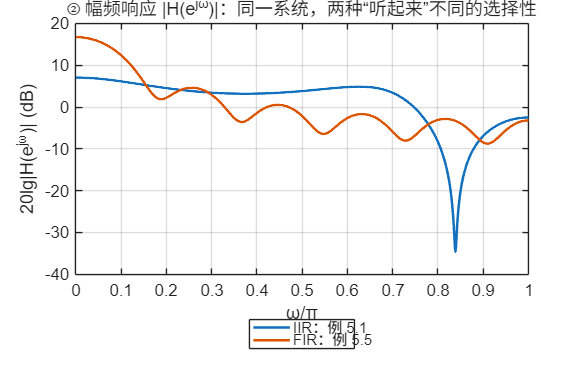

newpanel(); plot(w/pi, 20*log10(abs(HI)), 'LineWidth', 1.5); hold on; plot(w/pi, 20*log10(abs(HF)), 'LineWidth', 1.5);
grid on; xlabel('ω/π'); ylabel('20lg|H(e^{jω})| (dB)');
title('② 幅频响应 |H(e^{jω})|：同一系统，两种“听起来”不同的选择性'); legend('IIR：例 5.1', 'FIR：例 5.5');

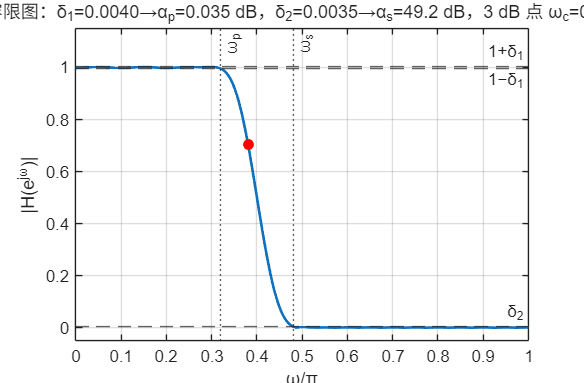

newpanel(); plot(w/pi, magL, 'LineWidth', 1.6); hold on;
yline(1 + d1, '--', '1+δ_1'); yline(1 - d1, '--', '1−δ_1', 'LabelVerticalAlignment', 'bottom'); yline(d2, '--', 'δ_2');
xline(wp/pi, ':', 'ω_p'); xline(ws/pi, ':', 'ω_s'); plot(w3/pi, magL(i3), 'ro', 'MarkerFaceColor', 'r');
grid on; xlabel('ω/π'); ylabel('|H(e^{jω})|'); ylim([-0.05 1.15]);
title(sprintf('③ 容限图：δ_1=%.4f→α_p=%.3f dB，δ_2=%.4f→α_s=%.1f dB，3 dB 点 ω_c=%.3fπ', d1, ap, d2, as, w3/pi));

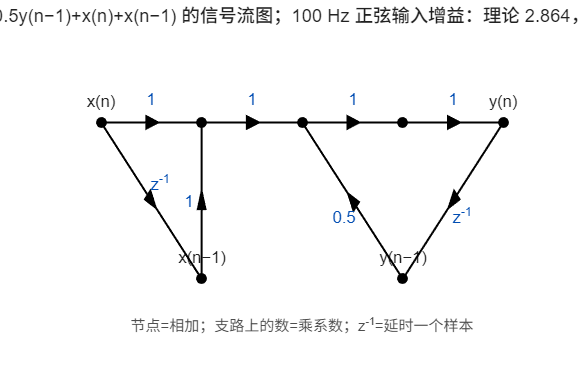

newpanel(); draw_sfg();
title(sprintf('④ y(n)=0.5y(n−1)+x(n)+x(n−1) 的信号流图；100 Hz 正弦输入增益：理论 %.3f，实测 %.3f', gainTheory, gainMeas));

if ~LIVE, sgtitle('数字滤波器：IIR/FIR 的区别在有没有反馈；指标用容限图和 dB 说话；结构用信号流图画出来'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '01-filter-concepts.png'), 'Resolution', 150); end

## 教师核验

assert(maxPole < 1, '例 5.1 应当稳定');
assert(all(hF30(12:end) == 0) && abs(hI(Nh)) > 0, 'FIR 应有限长、IIR 应无限长');
assert(d1 < 0.01 && as > 40, '示例低通指标不符预期');
assert(abs(gainTheory - gainMeas) < 0.01, '正弦稳态增益与频率响应不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'iir_max_pole_radius', maxPole, 'iir_h29', hI(Nh), 'fir_length', numel(hF), ...
    'delta1', d1, 'delta2', d2, 'alpha_p_dB', ap, 'alpha_s_dB', as, 'w3dB_over_pi', w3/pi, 'wp_over_pi', wp/pi, 'ws_over_pi', ws/pi, ...
    'gain_100Hz_theory', gainTheory, 'gain_100Hz_measured', gainMeas, 'phase_100Hz_deg', angle(H5)*180/pi, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-filter-concepts.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

         matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                 run_at: '2026-09-18 20:50:06'
    iir_max_pole_radius: 0.6701
                iir_h29: 1.4605e-05
             fir_length: 11
                 delta1: 0.0040
                 delta2: 0.0035
             alpha_p_dB: 0.0352
             alpha_s_dB: 49.2231
           w3dB_over_pi: 0.3803
             wp_over_pi: 0.3200
             ws_over_pi: 0.4800
      gain_100Hz_theory: 2.8643
    gain_100Hz_measured: 2.8643
        phase_100Hz_deg: -44.2677
      all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results


## 本地函数

function H = dtft_resp(b, a, w)
% H(e^{jω}) = Σ b_r e^{-jωr} / Σ a_k e^{-jωk}（多项式按 z^{-1} 的幂排列）
z = exp(-1i*w(:).');
H = polyval(fliplr(b), z) ./ polyval(fliplr(a), z);
end

function y = mysinc(x)
y = ones(size(x)); i = x ~= 0; y(i) = sin(pi*x(i)) ./ (pi*x(i));
end

function draw_sfg()
% 画 y(n)=0.5y(n−1)+x(n)+x(n−1) 的信号流图：节点为圆点，支路标增益，z^{-1} 为单位延时
axis off; hold on; xlim([-0.5 8.5]); ylim([-1.8 2.2]);
P = [0 1; 2 1; 4 1; 6 1; 8 1; 2 -1; 6 -1];           % x, A(加法), B(加法), y', y, xd, yd
names = {'x(n)', '', '', '', 'y(n)', 'x(n−1)', 'y(n−1)'};
plot(P(:,1), P(:,2), 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6);
for i = 1:size(P,1), text(P(i,1), P(i,2)+0.28, names{i}, 'HorizontalAlignment', 'center', 'FontSize', 10); end
arrow(P(1,:), P(2,:), '1'); arrow(P(2,:), P(3,:), '1'); arrow(P(3,:), P(4,:), '1'); arrow(P(4,:), P(5,:), '1');
arrow(P(1,:), P(6,:), 'z^{-1}'); arrow(P(6,:), P(2,:), '1');
arrow(P(5,:), P(7,:), 'z^{-1}'); arrow(P(7,:), P(3,:), '0.5');
text(4, -1.6, '节点=相加；支路上的数=乘系数；z^{-1}=延时一个样本', 'HorizontalAlignment', 'center', 'FontSize', 9, 'Color', [0.3 0.3 0.3]);
end

function arrow(p, q, label)
plot([p(1) q(1)], [p(2) q(2)], 'k-', 'LineWidth', 1.2);
m = (p + q)/2; d = (q - p)/norm(q - p); nrm = [-d(2) d(1)];
tri = [m + 0.18*d; m - 0.12*d + 0.1*nrm; m - 0.12*d - 0.1*nrm];
patch(tri(:,1), tri(:,2), 'k', 'EdgeColor', 'none');
text(m(1) + 0.25*nrm(1), m(2) + 0.3*nrm(2), label, 'HorizontalAlignment', 'center', 'FontSize', 10, 'Color', [0 0.3 0.7]);
end

function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end